# Модулятор

# Single Sideband Transmitted Carrier 

# (AM-SSB-TC)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

Как упоминалось в части SSB SC, основное преимущество однополосной модуляции заключается в двухкратном уменьшении полосы модулированного сигнала по сравнению с обычной DSB модуляцией. Так как огибающая SSB SC сигнала не совпадает с информационным сообщением, его прием возможен только когерентным методом. Поэтому необходимо точно восстановить частоту и фазу несущей. Для сигналов DSB SC для этого можно применить PLL с возведением сигнала в квадрат или схему Костаса. Для SSB SC сигнала, к сожалению, эти методы не работают. Поэтому часто вместе с однополосным сигналом передается несущая, которая позволяет применить обычную PLL для когерентной демодуляции. Такой сигнал называется SSB TC. Также при определенных условиях для SSB TC сигналов можно применять некогерентный приемник. 

### 2. Однотональная модуляция с использованием преобразования Гильберта

Методы модуляции SSB TC ни чем не отличаются от однополосной модуляции с подавленной несущей (SSB SC). Поэтому сразу рассмотрим модулятор на основе преобразования Гильберта. 

Комплексный сигнала с односторонним спектром можно получить из исходного сообщения с помощью преобразования Гильберта, которое представляет из себя всепропускающий фильтр, который изменяет только фазу сигнала. Преобразование Гильберта формирует мнимую часть аналитического сигнала. Таким образом, можем записать:


$$m_A \left(t\right)=m\left(t\right)+j\cdot m_H \left(t\right),$$


где $m\left(t\right)$ - исходное информационное сообщение, $m_H \left(t\right)=H\left\lbrace m\left(t\right)\right\rbrace$ - преобразование Гильберта от сообщения, $m_A \left(t\right)$ - аналитический сигнал с односторонним спектром.

Этот аналитический сигнал можно перенести на несущую частоте с помощью умножения на комплексную экспоненту. В результате сигнал останется комплексным. Чтобы сделать его вещественным нужно, оставить только его действительную часть. Однако, это приведет к тому, что в спектре сигнала в явном виде не будет содержаться гармоники на несущей частоте. Это можно исправить, если перед переносом спектра к действительной части аналитического сигнала добавить постоянную составляющую:


$$m_{A\;\mathrm{TC}} \left(t\right)=m\left(t\right)+A+j\cdot m_H \left(t\right),$$
 

где $A$ амплитуда несущей.

После умножения на комплексную экспоненту и выделения дейсвительной части получим USB сигнал, содержащий только верхнюю половину полосы частот сообщения. В виде формул данные преобразования можно записать так:

$s_{\mathrm{USB}} \left(t\right)=\mathrm{Real}\left\lbrace m_{A\;\mathrm{TC}} \left(t\right)\cdot e^{j\cdot 2\pi \cdot f_c \cdot t} \right\rbrace$.

Структурная схема передатчика предсталена ниже:

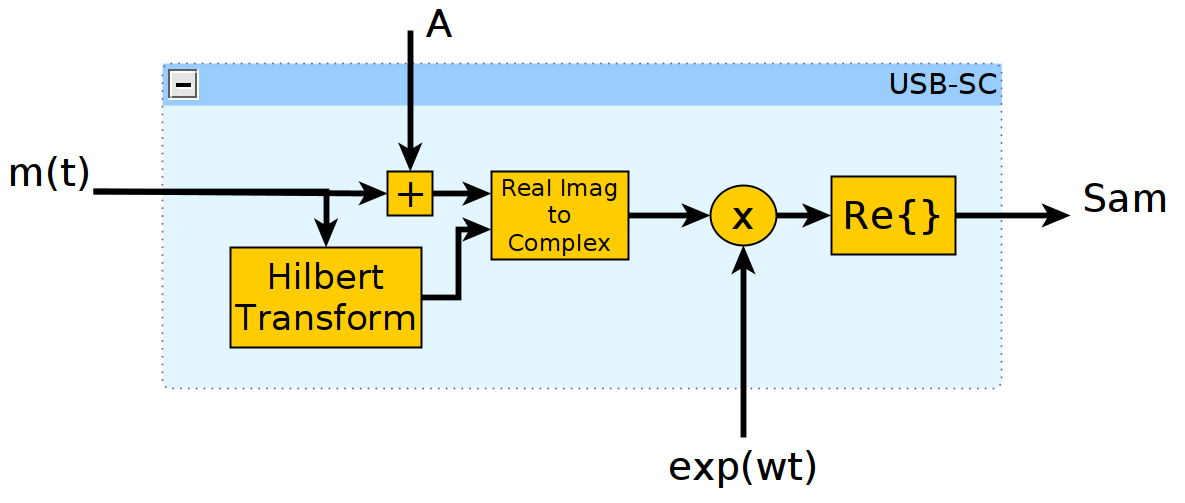

Если представить комплексную экспонету и аналитический сигнал как сумму действительной и мнимой части, то выражение для $s_{\textrm{USB}} \left(t\right)$ можно переписать в виде:


$$s_{\mathrm{USB}} \left(t\right)=\mathrm{Real}\left\lbrace \left(m\left(t\right)+A+j\cdot m_H \left(t\right),\right)\cdot \left(\cos \left(2\pi \cdot f_c \cdot t\right)+j\cdot \sin \left(2\pi \cdot f_c \cdot t\right)\right)\right\rbrace =$$



$$=\mathrm{Real}\left\lbrace \left(\left(m\left(t\right)+A\right)\cdot \cos \left(2\pi \cdot f_c \cdot t\right)-m_H \left(t\right)\cdot \sin \left(2\pi \cdot f_c \cdot t\right)\right)+j\cdot \left(m_H \left(t\right)\cdot \cos \left(2\pi \cdot f_c \cdot t\right)+\left(m\left(t\right)+A\right)\cdot \sin \left(2\pi \cdot f_c \cdot t\right)\right)\right\rbrace =$$


$=\left(m\left(t\right)+A\right)\cdot \cos \left(2\pi \cdot f_c \cdot t\right)-m_H \left(t\right)\cdot \sin \left(2\pi \cdot f_c \cdot t\right)$.

Таким образом, схему приемника можно представить в виде:

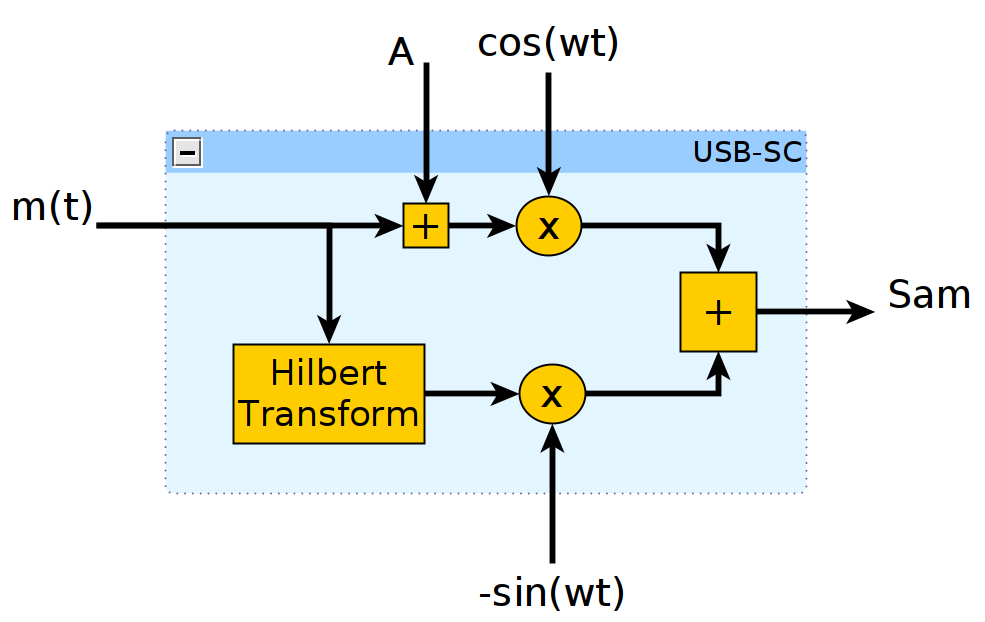

Если провести комплексное сопряжение аналитического сигнала, то получим сигнал, который содержит только отрицательные частоты. После добавления постоянной составляющей, переноса на спектра несущую частоту и выделения действительной части получим LSB сигнал. То есть, имеем:

$s_{\mathrm{LSB}} \left(t\right)=\mathrm{Real}\left\lbrace \left(m_A^* \left(t\right)+A\right)\cdot e^{j\cdot 2\pi \cdot f_c \cdot t} \right\rbrace$.

Структурная схема передатчика предсталена ниже:

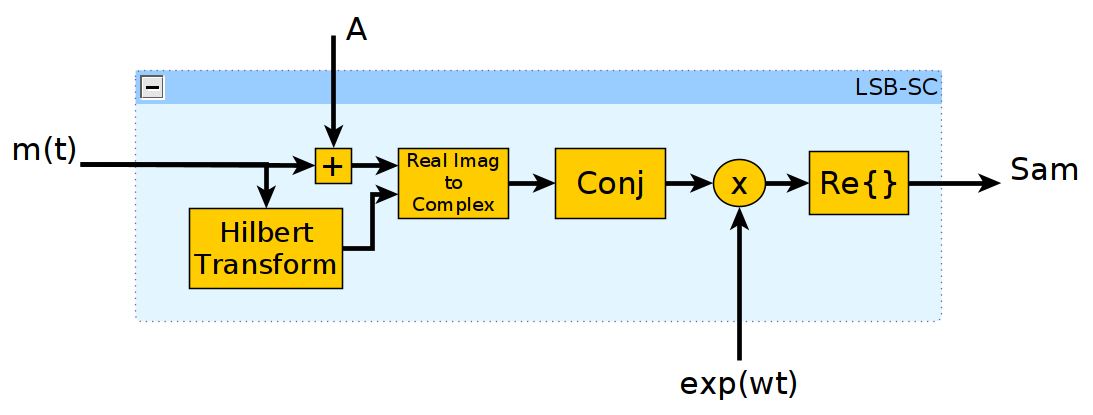

Если представить комплексную экспонету и аналитический сигнал как сумму действительной и мнимой части, то выражение для $s_{\textrm{LSB}} \left(t\right)$ можно переписать в виде:

$s_{\mathrm{LSB}} \left(t\right)=\left(m\left(t\right)+A\right)\cdot \cos \left(2\pi \cdot f_c \cdot t\right)+m_H \left(t\right)\cdot \sin \left(2\pi \cdot f_c \cdot t\right)$.

Таким образом, схему приемника можно представить в виде:

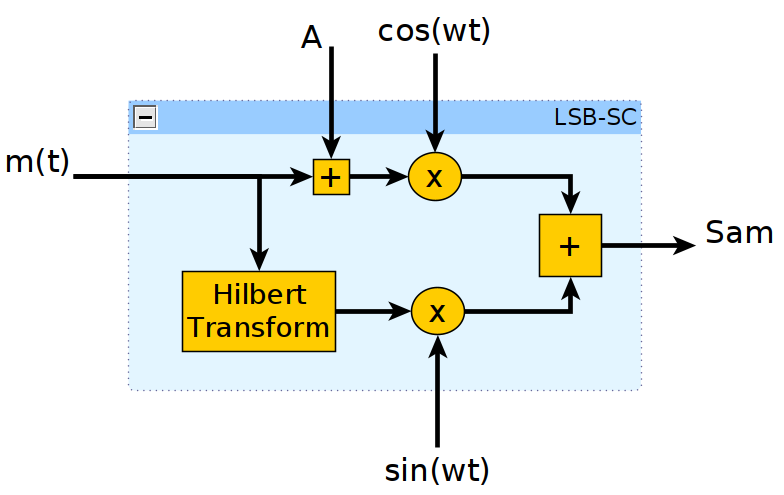

Рассмотрим данный метод формирования однополосного сигнала для однотональной модуляции. В этом случае информационное сообщение представляет из себя гармонический сигнал вида: 

$m\left(t\right)=A_m \cos \left(2\pi f_m t\right)$,

где $A_m$ - амплитуда тона, $f_m$ - частота в герцах. 

Преобразование Гильберта от косинуса равно синусу той же частоты. Значит можем записать:


$$m_H \left(t\right)=A_m \sin \left(2\pi f_m t\right)\ldotp$$


Таким образом, аналитичечкий сигнал можно представить в виде:


$$m_A \left(t\right)=m\left(t\right)+j\cdot m_H \left(t\right)=A_m \cos \left(2\pi f_m t\right)+j\cdot A_m \sin \left(2\pi f_m t\right)=A_m \cdot e^{j\cdot 2\pi \cdot f_m \cdot t} \ldotp$$


После добавления постоянной составляющей, переноса на несущую частоту с помощью умножения на комплексную экспоненту и взятия действительной части получим:


$$s_{\mathrm{USB}} \left(t\right)=\mathrm{Real}\left\lbrace \left(A_m \cdot e^{j\cdot 2\pi \cdot f_m \cdot t} +A\right)\cdot e^{j\cdot 2\pi \cdot f_c \cdot t} \right\rbrace =\mathrm{Real}\left\lbrace A_m \cdot e^{j\cdot 2\pi \cdot \left(f_m +f_c \right)\cdot t} +A\cdot e^{j\cdot 2\pi \cdot f_c \cdot t} \right\rbrace =\mathrm{Acos}\left(2\pi f_c t\right)+A_m \cos \left(2\pi \left(f_c +f_m \right)t\right)\ldotp$$


То есть, как и ожидалось, USB сигнал для однотональной модуляции состоит из единственного тона на частоте $f_c +f_m$ и тона на частоте несущей. 

Чтобы получить LSB сигнал, необходимо предварительно произвести комплексное сопряжение аналитического сигнала. В связи с этим можем записать:


$$m_A^* \left(t\right)=A_m \cdot e^{-j\cdot 2\pi \cdot f_m \cdot t} \ldotp$$



$$s_{\mathrm{LSB}} \left(t\right)=\mathrm{Real}\left\lbrace \left(A_m \cdot e^{-j\cdot 2\pi \cdot f_m \cdot t} +A\right)\cdot e^{j\cdot 2\pi \cdot f_c \cdot t} \right\rbrace =\mathrm{Real}\left\lbrace A_m \cdot e^{j\cdot 2\pi \cdot \left(f_c -f_m \right)\cdot t} +A\cdot e^{j\cdot 2\pi \cdot f_c \cdot t} \right\rbrace =\mathrm{Acos}\left(2\pi f_c t\right)+A_m \cos \left(2\pi \left(f_c -f_m \right)t\right)\ldotp$$


То есть, LSB сигнал для однотональной модуляции состоит из единственного тона на частоте $f_c -f_m$ и тона на частоте несущей. 

Ниже представлен скрипт для получения спектра однополосного сигнала с помощью преобразования Гильберта для однотональной модуляции. С помощью переменной ModulationMethod можно выбрать, какой вид модуляции будет использован (USB или LSB):

clc; clear; close all;

FrameSize = 5000;   % размер обрабатываемой за один раз пачки данных
Fs = 100e3;         % тактовая частота (Hz)
Ac = 1.5;           % амплитуда несущей 

% выбор метода модуляции
ModulationMethod = "LSB"; 

% генератор однотонального сигнала
% частота тона: 5 kHz
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', 5e3,...
    'Amplitude', 1 ...
    );

% генератор несущей
% частота несущей: 35 kHz
Carrier = dsp.SineWave(...
    'SampleRate', Fs,...
    'SamplesPerFrame', FrameSize,...
    'Frequency', 35e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% формирует аналитический сигнал
HilbertTranform = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-30, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Analytic Message', 'Message', 'SSB AM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();

    % формирование аналитического сигнала
    AnalyticData = HilbertTranform(MessageData);

    % добавление постоянной составляющей
    AnalyticData = AnalyticData + Ac;
    
    % формирование несущей
    CarrierWave = Carrier(); 

    % однополосная модуляция
    if (ModulationMethod == "USB")
        SSBAmSignal = real(AnalyticData.*CarrierWave);
    else
        SSBAmSignal = real(conj(AnalyticData).*CarrierWave);
    end
    
    % вычисление спектров
    Spectrums = SpecEstimator([AnalyticData, MessageData, SSBAmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

На графике представлен спектр информационного сигнала (синий) и спектр аналитического сигнала (желтый) с добавленной постоянной составляющей. В зависимости от вида модуляции (USB или LSB) аналитический сигнал будет располагаться только на положительных или только на отрицательных частотах. Также можно увидеть, что, как и ожидалось, модулированный сигнал состоит из одного тона информационного сообщения и тона несущей.

### 4. Модуляция несколькими тонами

Разобравшись с однотональной модуляцией, легко распространить результаты на случай модуляции несколькими тонами. Пусть информационный сигнал представляет из себя сумму гармонических сигналов:

$m\left(t\right)=\sum_{i=1}^N A_i \cos \left(2\pi f_i t\right)$,

Рассмотрим, что происходит в частотной области. В случае обычной DSB модуляции несколькими тонами модулированный сигнал примет следующий вид:  

$s_{\textrm{am}} \left(t\right)=\sum_{i=1}^N A_i \cos \left(2\pi f_i t\right)\cdot A_c \cos \left(2\pi f_c t\right)=\frac{A_c }{2}\sum_{i=1}^N A_i \left\lbrack \cos \left(2\pi \left(f_i +f_c \right)t\right)+\cos \left(2\pi \left(f_i -f_c \right)t\right)\right\rbrack$.

То есть, после модуляции каждому тону будут соответстовать две гармоники на частотах $f_i +f_c$ и $f_i -f_c$. Как упоминалось ранее, начилие двух тонов приводит к удвоению спектра. С помощью преобразования Гильберта можно удалить половину спектра информационного сообщения, после чего добавить к сигналу несущую. Построим спектры сигналов для случая модуляции тремя тонами.

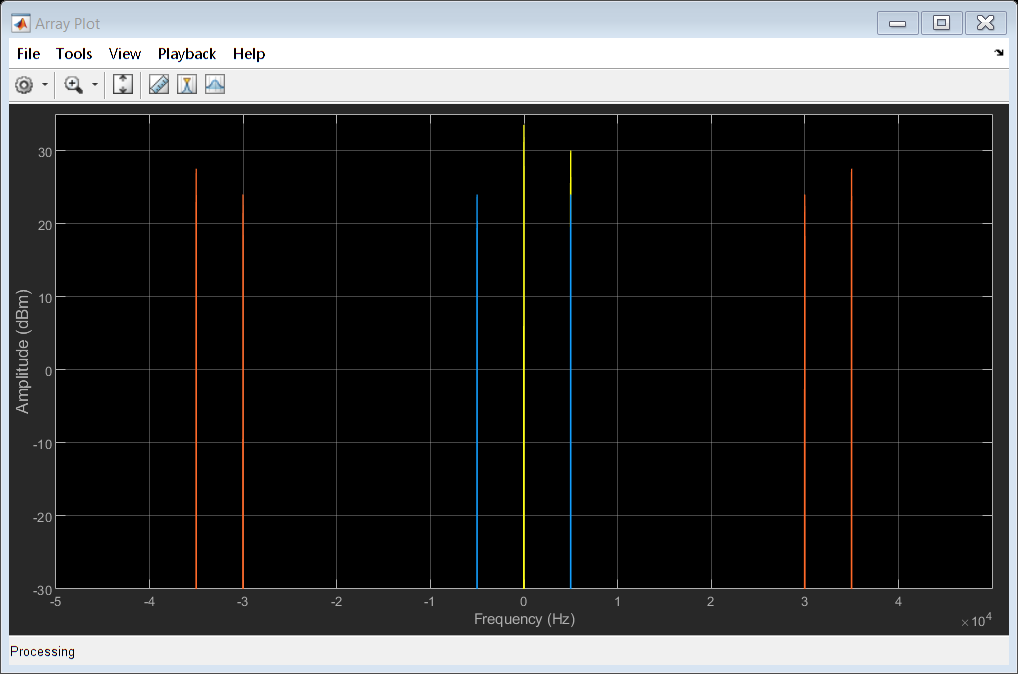

clc; clear; close all;

FrameSize = 5000;   % размер обрабатываемой за один раз пачки данных
Fs = 200e3;         % тактовая частота (Hz)
Ac = 1.5;           % амплитуда несущей 

% выбор метода модуляции
ModulationMethod = "LSB"; 

% генератор информационного сигнала из трех тонов
% частота тонов: 5, 8 и 13 kHz
% амплитуды тонов: 0.1, 0.5 и 0.7
Message = dsp.SineWave(...
    'SampleRate', Fs,...
    'SamplesPerFrame', FrameSize,...
    'Frequency', [5e3 8e3 13e3],...
    'Amplitude', [0.1 0.5 0.7]);

% генератор несущей
% частота несущей: 35 kHz
Carrier = dsp.SineWave(...
    'SampleRate', Fs,...
    'SamplesPerFrame', FrameSize,...
    'Frequency', 50e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% формирует аналитический сигнал
HilbertTranform = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',Fs ...
    );

% объект для отрисовки графиков

Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-20, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'SSB Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% запуск симуляции
for i = 1:100
    % формирование информационного сигнала
    MessageData = Message();
    MessageData = MessageData(:,1) + MessageData(:,2) + MessageData(:,3);

    % формирование аналитического сигнала
    AnalyticData = HilbertTranform(MessageData);
    
    % добавление постоянной составляющей
    AnalyticData = AnalyticData + Ac;

    % формирование несущей
    CarrierWave = Carrier(); 

    % однополосная модуляция
    if (ModulationMethod == "USB")
        SSBAmSignal = real(AnalyticData.*CarrierWave);
    else
        SSBAmSignal = real(conj(AnalyticData).*CarrierWave);
    end
    
    % вычисление спектров
    Spectrums = SpecEstimator([MessageData, SSBAmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Можно увидеть, что спектр модулированного сигнала (синий) в зависимости от вида модуляции соответсвует  верхней или нижней половине спектра информационного сообщения (желтый). Так же в спектре присутстует гармоника на несущей частоте.

### 5. Модуляция звуковым сигналом

Рассмотрим, как будет выглядеть спектр сигнала после однополосной модуляции, если информационное сообщение является аудиосигналом. В файле Audio_Source.wav записано звуковое сообщение с частотой дискретизации 44.1 kHz. Частота несущей будет равна 60 kHz. Чтобы избежать наложения спектров, выберем итоговую частоту дискретизации модулированного сигнала в 5 раз больше частоты аудиосигнала, то есть 5 * 44.1 kHz. Это потребует провести интерполяцию для увеличения частоты дискретизации информационного сообщения.

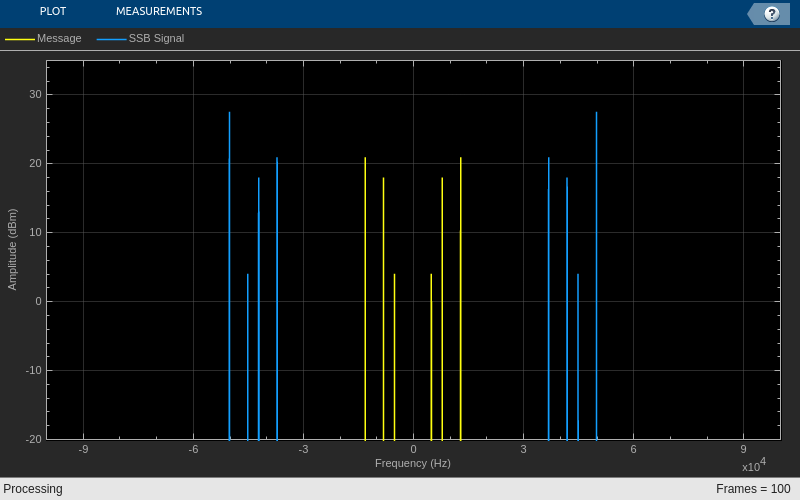

clc; clear; close all;

AudioFrameSize = 1000;  % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 100;     % число обрабатываемых пачек данных
RateRatio = 5;          % коэффициент увеличения частоты дискретизации
Ac = 1.5;               % амплитуда несущей 

% выбор метода модуляции
ModulationMethod = "LSB"; 

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% генератор несущей с частотой 60 kHz
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% объект вычисления преобразования Гильберта
% формирует аналитический сигнал
HilbertTranform = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);


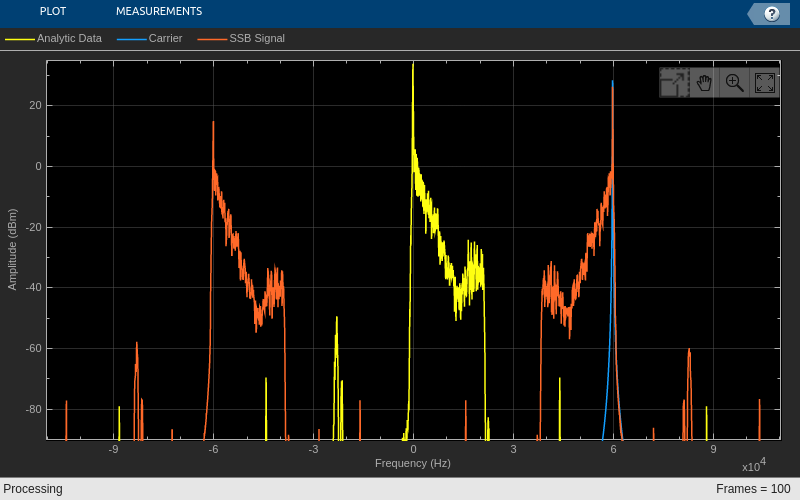

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Analytic Data', 'Carrier', 'SSB Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);
    
    % формирование аналитического сигнала
    AnalyticData = HilbertTranform(AudioData);

    % добавление постоянной составляющей
    AnalyticData = AnalyticData + Ac;

    % увеличение частоты дискретизации аудиосообщения
    UpsampledData = Upsampler(AnalyticData);
     
    % формирование несущей
    CarrierWave = Carrier(); 

    % однополосная модуляция
    if (ModulationMethod == "USB")
        SSBAmSignal = real(UpsampledData.*CarrierWave);
    else
        SSBAmSignal = real(conj(UpsampledData).*CarrierWave);
    end
    
    % вычисление спектров
    SpectrumData = SpecEstimator([UpsampledData, CarrierWave, SSBAmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Можно увидеть,что в результате преобразования Гильберта удаление одной из половин спектра сообщения выполняется не идеально. На спектре видны остатки подавленной половины.  Эти остатки могут влиять на соседние каналы связи. В нашем примере амплитуда подавленных спектральных компонентов отличается от передаваемого сигнала почти на 40 дБ. В зависимости от требований к передатчику этого может быть достаточно, а может быть и нет.

### 8. Преимущества и недостатки SSB-TC

####     Преимущества:

- уменьшение вдвое ширины спектра модулированного сигнала;

- возможно применение обычной PLL для когерентного приема;

- при определенных условиях можно использовать некогерентный приемник.

####     Недостатки:

- модуляция менее эффективна с точки зрения мощности, так как несущая передается.

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR